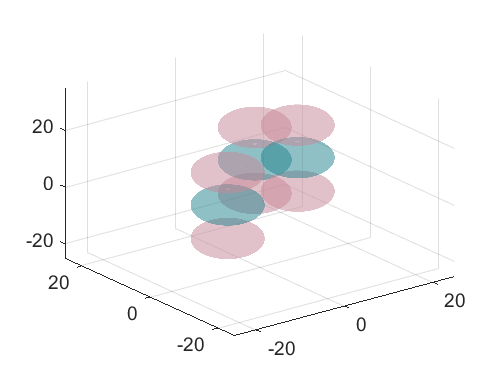

clear all
ax = axes('XLim',[-25 25],'YLim',[-25 25],'ZLim',[-25 35]);
view(3)

R1=6.68;
R3=5.67;

[x1,y1,z1] = ellipsoid(-7.33,0,0,R1,R1,R3,50);
[x2,y2,z2] = ellipsoid(-7.33,0,-11.81,R1,R1,R3,50);
[x3,y3,z3] = ellipsoid(-7.33,0,11.46,R1,R1,R3,50);
hold on

h(1)=surf(x1,y1,z1,'FaceColor',[36,133,142]/256,'EdgeColor','none','FaceAlpha',0.3);
h(2)=surf(x2,y2,z2,'FaceColor',[200,137,153]/256,'EdgeColor','none','FaceAlpha',0.3);
h(3)=surf(x3,y3,z3,'FaceColor',[200,137,153]/256,'EdgeColor','none','FaceAlpha',0.3);
grid on
hold off

t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);

Rx = makehgtform('xrotate',pi/4);
Ry = makehgtform('yrotate',pi/6);
Rz = makehgtform('zrotate',-2*pi/3);

Tz1 = makehgtform('translate',[0 0 7.76]);
Tz2 = makehgtform('translate',[0 0 -11.81]);
Tz3 = makehgtform('translate',[0 0 11.46]);
Ty = makehgtform('translate',[7.73 0 0]);

set(h,'Parent',t1);

h2 = copyobj(h,t2);
h3 = copyobj(h,t3);


set(t2,'Matrix',Rz*Tz1)
set(t3,'Matrix',(Rz*Tz1)^2)

drawnow

for i = 1:360
   camorbit(1,0,'data',[0 0 1])

   drawnow
end